## Note: this file will take a preprocessed EEG dataset, determine an appropriate baseline, and feed it into a Gaussian Mixture Model (GMM)

## read in filtered data

% load in the filtered dataset
%allEDFs_filtered = allEDFs

## BASELINE 

% find index of first instance of "intubat" (intubation)
intubation_Index = find_indx(allEDFs_filtered, 'intubat')

intubation_Index = 764289


% find index of first instance of "incis" (incision)
incision_Index = find_indx(allEDFs_filtered, 'incis')

incision_Index = 1613825

% run function to determine start index for each EEG channel
channels = allEDFs_filtered.data{'EEG'}.Properties.VariableNames;
if length(channels) ~= 8
    fprintf("Warning: number of channels does not equal 8");
end



table_size = size(allEDFs_filtered.data{'EEG'}); % determine size of table for for loop
% start_index = nan(1,table_size(1,2));
% for k = 1:length(channels) 
%     % TODO: once "EEG_PreProcess.mlx" is complete, modify method for determining start index. 
%     % all of those repeated values should become nan so we just need to take values after that point.
%     start_index(1,k) = baseline_mean(table_size, allEDFs_filtered, channels(1,k));
% end
% start_index % check for baseline start

% check that there is not a lot of variance between start_index values. too
% large of a difference could indicate a problem with the baseline
% determination values and would need to be evaluated on a case-by-case
% basis
% diffs = diff(start_index);
% diffs = max(abs(diffs(diffs >= 0)));
% if (diffs > 5)
%     error("large variance among baseline start indices detected. largest difference was determined to be " + diffs)
% end


## test

% % entire baseline
% test_full_filtered = allEDFs_filtered.data{'EEG'}{intubation_Index:incision_Index,:};
% test_no_mode = allEDFs_nomode.data{'EEG'}{intubation_Index:incision_Index,:};
% test_no_sat = allEDFs_nosaturation.data{'EEG'}{intubation_Index:incision_Index,:};
% isnan(test_full_filtered)
% % null_values = find(isnan(test_full_filtered))
% % %test_full_filtered(isnan(test_full_filtered))
% % test_no_sat(null_values)
% % explore = test_no_mode(null_values)
% % explore(explore>60)
% % explore(explore>70)
% % explore(explore>80)
% % explore(explore>90)
% % explore(explore>100)
% % explore(explore>200)
% 
% rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
% sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
% window_size = sample_rate * 15;
% 
% window_analysis = windowed_data(incision_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_filtered, window_size,channels)
% analysis_nomode = windowed_data(incision_Index+1, size(allEDFs_nomode.data{'EEG'}(:,1)), allEDFs_nomode, window_size,channels)
% analysis_nosat = windowed_data(incision_Index+1, size(allEDFs_nosaturation.data{'EEG'}(:,1)), allEDFs_nosaturation, window_size,channels)
% 
% Fs = allEDFs_filtered.info{'EEG'}.NumSamples(1,1)/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration(1,1));   % sampling rate
% L = length(window_analysis)
% N = L % end point
% f = (Fs*(0:((L-1)/2))/L); % frequency
% transforms_analysis = fft(window_analysis, N, 1)/L; % returns each band being == 1Hz
% single_sided_transform = transforms_analysis(1:L/2, :, :);
% plot(f, single_sided_transform(:,1,1))
% xlabel('Frequency')
% ylabel('Amplitude')
% title('Fourier Transform - full process')
% 
% transforms_analysis = fft(analysis_nomode, N, 1)/L; % returns each band being == 1Hz
% single_sided_transform = transforms_analysis(1:L/2, :, :);
% plot(f, single_sided_transform(:,1,1))
% xlabel('Frequency')
% ylabel('Amplitude')
% title('Fourier Transform - no mode')
% 
% transforms_analysis = fft(analysis_nosat, N, 1)/L; % returns each band being == 1Hz
% single_sided_transform = transforms_analysis(1:L/2, :, :);
% plot(f, single_sided_transform(:,1,1))
% xlabel('Frequency')
% ylabel('Amplitude')
% title('Fourier Transform - no sat')

## baseline mean determination (single value/channel)

% baseline_preIntubation = nan(1,8);
% baseline_postIntubation = nan(1,8);
% baseline_Total = nan(1,8);
% for i = 1:table_size(1,2)
%     baseline_preIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):intubation_Index, channels(1,i)},'omitnan');  
%     baseline_postIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{intubation_Index:incision_Index, channels(1,i)},'omitnan');  
%     baseline_Total(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):incision_Index, channels(1,i)},'omitnan');
% end
% baseline_preIntubation
% baseline_postIntubation
% baseline_Total

## baseline mean determination (15 sec window/channel)


% 15 second windows
    % data from baseline regions is divided into 15 second windows and then
    % the mean is calculated to create one 15 second array per channel

rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
window_size = sample_rate * 15;

%preintubation_mean_baseline_window = mean_baseline_windowed(start_index, intubation_Index, allEDFs_filtered, window_size, channels)
%postintubation_mean_baseline_window = mean_baseline_windowed(intubation_Index, incision_Index, allEDFs_filtered, window_size, channels)
%total_mean_baseline_window = mean_baseline_windowed(start_index, incision_Index, allEDFs_filtered, window_size, channels)  

## baseline window determination (3D - for GMM)

%window_preintubation_baseline = windowed_data(start_index, intubation_Index, allEDFs_filtered, window_size,channels)
window_postintubation_baseline = windowed_data(intubation_Index, incision_Index, allEDFs_filtered, window_size,channels)

window_postintubation_baseline = window_postintubation_baseline(:,:,1) =

   -3.5622   -4.4531    1.9734   -7.7500   -3.9048   -4.4226
    1.1967    4.0901    0.2982   -2.2602   -2.6866   -2.4125
    1.9886    4.9429    0.3972    1.0368    4.3947   -1.7424
    1.9505    4.5774    1.1282   -1.2855    4.5165   -1.2475
    1.5850    2.7500    1.6459   -1.5064    3.6637    1.6155
    0.5495    0.9150    1.7297   -1.0114    1.8287    2.9632
   -0.2424   -0.1815    1.5774    0.4505   -0.8515    3.8160
   -0.4860    0.4277    1.4404    0.3058   -2.4429    4.1206
    0.9150    1.6459    1.1967    1.5241   -3.7830    4.1053
    1.6459    3.2373    0.8617    3.9683   -3.8211    4.0368
    2.7500    3.9683    0.2221    5.6739   -2.8465    3.7932
    3.1155    4.0064    0.4657    5.9175   -1.0114    3.3668
    3.1612    2.7881    1.4099    5.3084   -2.3592    3.1460
    2.3617   -1.1180    2.1409    3.9683   -3.2119    3.0698
    1.8744   -1.6130    2.5749    2.8718   -3.3262    2.7652
    2.1180 

%test_nomode = windowed_data(intubation_Index, incision_Index, allEDFs_nomode, window_size,channels)
%test_nosat = windowed_data(intubation_Index, incision_Index, allEDFs_nosaturation, window_size,channels)
%window_total_baseline = windowed_data(start_index, incision_Index, allEDFs_filtered, window_size,channels)


## ANALYSIS 

% Note: from hospital team: abnormal events are annotated as alerts when duration
% of event exceeds 1 min

% from hospital team: abnormal events are observed when one or both
% hemishperes stray from baseline


## analysis window determination

window_analysis = windowed_data(incision_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_filtered, window_size,channels)

window_analysis = window_analysis(:,:,1) =

       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN 

%analysis_nomode = windowed_data(incision_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_nomode, window_size,channels)
%analysis_nosat = windowed_data(incision_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_nosaturation, window_size,channels)


%gm = fitgmdist(preintubation_baseline_window, 1) % how do we know how many components a GMM should be?
%properties(gm); % list all properties for the GMM. Can be accessed using format "gm.NumVariables" (dot notation)
% for each 15 second window, for each channel compute delta (1-3Hz) theta
% (4-7Hz) alpha (8-12Hz) beta (13-20Hz) gamma (30-100Hz) (spectral) - 40 measurements for each window (40 X #15-second
% windows you have), then feed it into gaussian mixture model


## gaussian mixture model



Fs = allEDFs_filtered.info{'EEG'}.NumSamples(1,1)/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration(1,1));   % sampling rate
L = length(window_analysis)

L = 1920

N = L % end point

N = 1920

f = (Fs*(0:((L-1)/2))/L); % frequency
transforms_analysis = fft(window_analysis, N, 1)/L; % returns each band being == 1Hz
single_sided_transform = transforms_analysis(1:L/2, :, :);
plot(f, single_sided_transform(:,1,1))

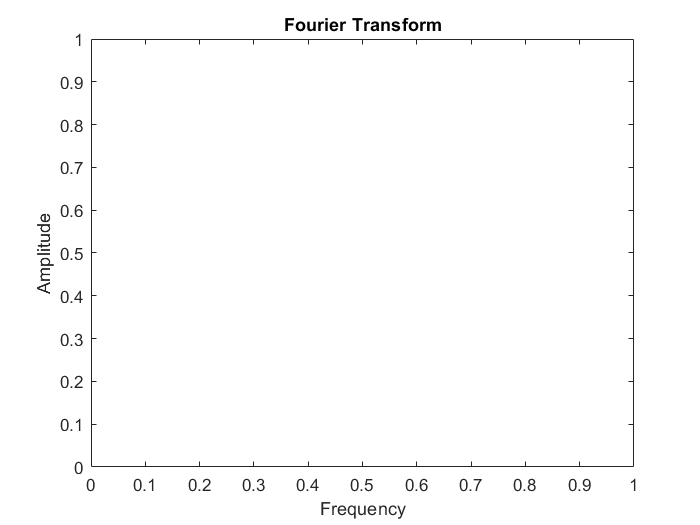

xlabel('Frequency')
ylabel('Amplitude')
title('Fourier Transform')

% spectral bands
 delta_analysis = spectral_bandpower(window_analysis, [1 3], Fs);
% delta_baseline = spectral_bandpower(window_postintubation_baseline, [1 3], Fs);
% theta_analysis = spectral_bandpower(window_analysis, [4 7], Fs);
% theta_baseline = spectral_bandpower(window_postintubation_baseline, [4 7], Fs);
% alpha_analysis = spectral_bandpower(window_analysis, [8 12], Fs);
% alpha_baseline = spectral_bandpower(window_postintubation_baseline, [8 12], Fs);
% beta_analysis = spectral_bandpower(window_analysis, [13 20], Fs);
% beta_baseline = spectral_bandpower(window_postintubation_baseline, [13 20], Fs);
% gamma_analysis = spectral_bandpower(window_analysis, [30 100], Fs); 
% gamma_baseline = spectral_bandpower(window_postintubation_baseline, [30 100], Fs);

spectral_bands = struct('delta', {spectral_bandpower(window_postintubation_baseline, [1 3], Fs),spectral_bandpower(window_analysis, [1 3], Fs)}, ...
    'theta',{spectral_bandpower(window_postintubation_baseline, [4 7], Fs), spectral_bandpower(window_analysis, [4 7], Fs)}, ...
    'alpha', {spectral_bandpower(window_postintubation_baseline, [8 12], Fs), spectral_bandpower(window_analysis, [8 12], Fs)}, ...
    'beta', {spectral_bandpower(window_postintubation_baseline, [13 20], Fs), spectral_bandpower(window_analysis, [13 20], Fs)}, ...
    'gamma', {spectral_bandpower(window_postintubation_baseline, [30 100], Fs), spectral_bandpower(window_analysis, [30 100], Fs)});



gm = fitgmdist(gamma_baseline(:,1:2), 1)

Unrecognized function or variable 'gamma_baseline'.

d8 = mahal(gm, gamma_baseline(:,1:2))
d9 = mahal(gm, gamma_analysis(1:219,1:2))
x = cluster(gm, delta_analysis(:,1:2))

% TODO: rn were looking at two channels, will need to look at all 8
% eventually
% TODO: optimize code eventually to increase speed -> create functions from
% various baseline determination methods. preallocate as well
% TODO: plot data meaningfully
% TODO: feedback from dr k
% TODO: more rigorous validation of mahal to determine if it is what we are
% looking for, as well as determining meaning of mahal distances. (also,
% are the mahal distances abnormal at alerts, as they should be?)

[P, nlogL] = posterior(gm, delta_baseline(:,1:2))

figure; 
gscatter(delta_baseline(:,1),delta_baseline(:,2), idx)
xlim([0 80])
ylim([0 80])
% can start with all of these dimensions and maybe go to less dimensions
% (principal component analysis)

%NOTE: GMM requires Statistics and Machine Learning Toolbox